%This script covers the main computational procedure detailed in the published main text.
%This example code was designed to run on data from Rengifo_Rodas et al. 2020 preprocessed as described in Manuello et al. 2025.
%The original dataset can be found here https://data.mendeley.com/datasets/xzv6bjm9x2/1 

%Coded by Jordi Manuello (M'N'B Lab, University of Torino) and Valeria Longatelli (Theoretical and Cognitive Neuroscience Unit, Scientific Institute IRCCS MEDEA) in December 2024.
%This code is distributed under the terms of the GNU General Public License
%GPL-3.

## Initialize code

clear all
close all
load('Example_data.mat'); %This contains the necessary data to run the example code

## **Computation of inter-events distance - Phase [I-a]** 

#### Compute Procrustes distance between each single step of each subject 

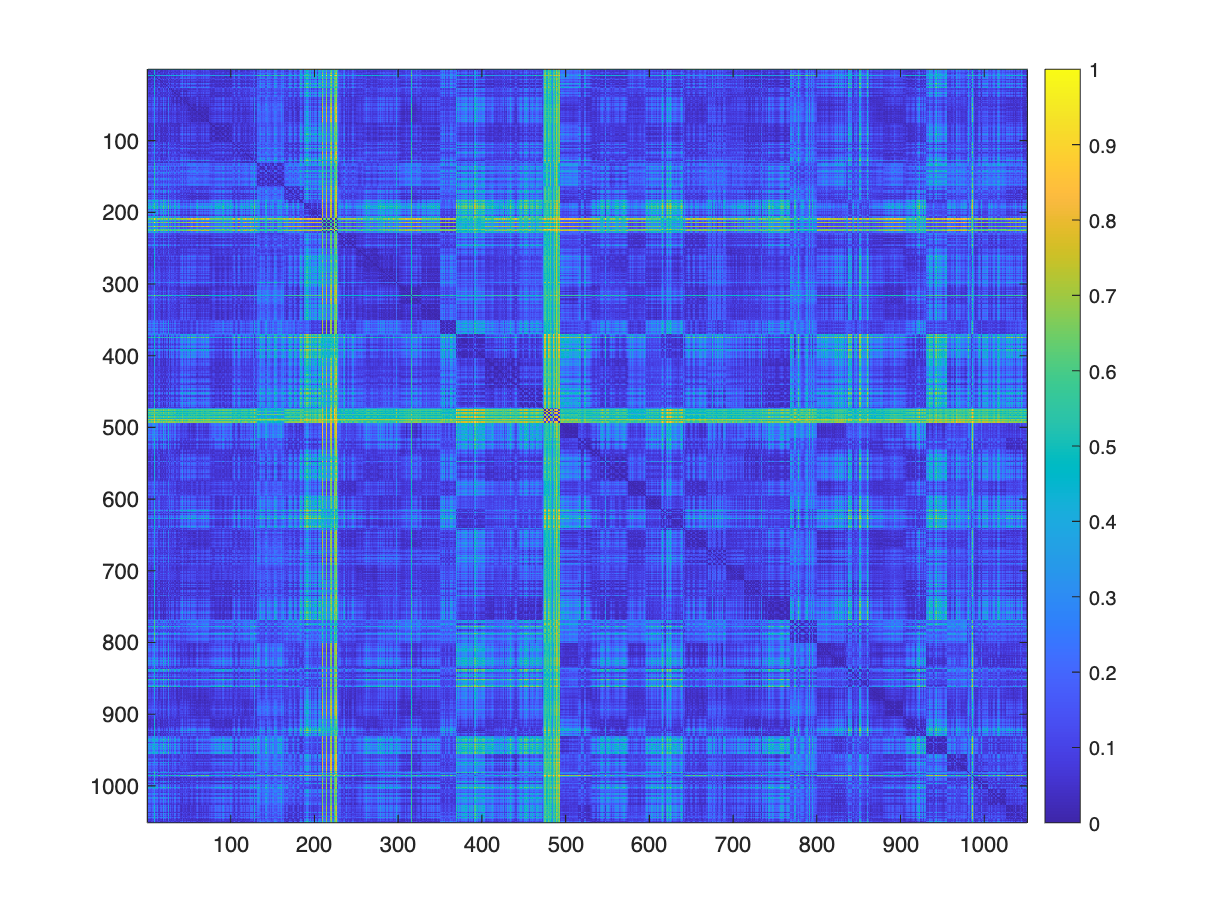

%Matrix_BRS is the (time-bins x varibles x steps) matrix
for targetrepetition=1:size(Matrix_BRS,3)
    TargetMatrix=Matrix_BRS(:,:,targetrepetition);
    for repetition=1:size(Matrix_BRS,3)
        [ProcrustesDistance_BRSMultiple(repetition,targetrepetition)]=procrustes(TargetMatrix,Matrix_BRS(:,:,repetition));
    end
end
ProcrustesDistance_BRSMultiple=ProcrustesDistance_BRSMultiple-diag(diag(ProcrustesDistance_BRSMultiple));

figure;
clim=[0 1];
f=imagesc(ProcrustesDistance_BRSMultiple,clim);
colormap('parula');
colorbar

clear f
%close all

## **Representation of the events in a lower dimensional space - Phase [I-b]**

#### Multidimensional scaling

SubjectNumber=SubjectNumber*2; %This is to work on the 2 instances for each of the 42 participants
DimensionsNumber=2; %This sets the dimensionality of the MDS
rng(1)
MDS_B_Base=cmdscale(round(ProcrustesDistance_BRSMultiple,6),DimensionsNumber);

figure
for subject=1:SubjectNumber
    if subject == 1
        hold on,p_b(subject)=plot(MDS_B_Base(1:StepNumber_Base(subject),1),MDS_B_Base(1:StepNumber_Base(subject),2),'o','MarkerSize', 8, 'LineWidth', 1.5);
    else
        hold on,p_b(subject)=plot(MDS_B_Base(StepNumber_Base(subject-1)+1:StepNumber_Base(subject),1),MDS_B_Base(StepNumber_Base(subject-1)+1:StepNumber_Base(subject),2),'o','MarkerSize', 8, 'LineWidth', 1.5);
        hold on
        xline(0)
        hold on
        yline(0)
        ylim([-0.35 0.35]),xlim([-0.5 0.5])
        set(gca,'Fontsize',14,'TickLabelInterpreter','latex')
        grid on
    end
end
%close all

## **Definition of the space of variability - Phase [II]**

1) Build ellipse: 

for subject=1:SubjectNumber

    if subject == 1
        % Center
        EllipseCenter_B_Base(subject,:)=[mean(MDS_B_Base(1:StepNumber_Base(subject),1)) mean(MDS_B_Base(1:StepNumber_Base(subject),2))];
        % Axes
        [Eigenvector_B_Base, Eigenvalue_B_Base]=eig(cov(MDS_B_Base(1:StepNumber_Base(subject),:)));
    else
        % Center
        EllipseCenter_B_Base(subject,:)=[mean(MDS_B_Base(StepNumber_Base(subject-1)+1:StepNumber_Base(subject),1)) mean(MDS_B_Base(StepNumber_Base(subject-1)+1:StepNumber_Base(subject),2))];
        % Axes
        [Eigenvector_B_Base, Eigenvalue_B_Base]=eig(cov(MDS_B_Base(StepNumber_Base(subject-1)+1:StepNumber_Base(subject),:)));
    end

    % Largest eigenvalue -> Major axes
    [Evec_Largest_B_Base_colindex,interim_row]=find(Eigenvalue_B_Base == max(max(Eigenvalue_B_Base)));
    Evec_Largest_B_Base=Eigenvector_B_Base(:, Evec_Largest_B_Base_colindex);
    Eval_Largest_B_Base=max(max(Eigenvalue_B_Base));
    % Smallest eigenvalue -> Minor axes
    if(Evec_Largest_B_Base_colindex == 1)
        Eval_Smallest_B_Base=max(Eigenvalue_B_Base(:,2));
        Evec_Smallest_B_Base=Eigenvector_B_Base(:,2);
    else
        Eval_Smallest_B_Base=max(Eigenvalue_B_Base(:,1));
        Evec_Smallest_B_Base=Eigenvector_B_Base(1,:);
    end

    % Calculate the angle between the x-axis and the largest eigenvector
    RotationAngle_B_Base(subject)=atan2(Evec_Largest_B_Base(2), Evec_Largest_B_Base(1));
    % Shift the rotation angle from [-pi; pi] to [0; 2pi]
    if(RotationAngle_B_Base(subject) < 0)
        RotationAngle_B_Base(subject)=RotationAngle_B_Base(subject) + 2*pi;
    end

    % Get the 95% confidence interval error ellipse
    chisquare_val=2.4477; % Inverse of the chi-square cumulative distribution for the 95% confidence interval
    theta_grid=linspace(0,2*pi);
    MahalanobisRadius=0.7; % Ref Slowinski

    AxisX_B_Base=chisquare_val*sqrt(Eval_Largest_B_Base)*MahalanobisRadius;
    AxisY_B_Base=chisquare_val*sqrt(Eval_Smallest_B_Base)*MahalanobisRadius;

    % Build ellipse in x and y coordinates -> Not rotated
    EllipseX_NoRot_B_Base=AxisX_B_Base*cos(theta_grid);
    EllipseY_NoRot_B_Base=AxisY_B_Base*sin(theta_grid);

    % Rotation matrix
    RotationMatrix_B_Base=[cos(RotationAngle_B_Base(subject)) sin(RotationAngle_B_Base(subject)); -sin(RotationAngle_B_Base(subject)) cos(RotationAngle_B_Base(subject))];

    % Rotate ellipse
    Ellipse_Rot_B_Base(:,:,subject)=[EllipseX_NoRot_B_Base;EllipseY_NoRot_B_Base]'*RotationMatrix_B_Base;

    % Find vertices of the ellipse
    Vertices(subject).B.V1=[EllipseCenter_B_Base(subject,1)+AxisX_B_Base*cos(RotationAngle_B_Base(subject)) EllipseCenter_B_Base(subject,2)+AxisX_B_Base*sin(RotationAngle_B_Base(subject))];
    Vertices(subject).B.V2=[EllipseCenter_B_Base(subject,1)-AxisX_B_Base*cos(RotationAngle_B_Base(subject)) EllipseCenter_B_Base(subject,2)-AxisX_B_Base*sin(RotationAngle_B_Base(subject))];
    Vertices(subject).B.V3=[EllipseCenter_B_Base(subject,1)-AxisY_B_Base*sin(RotationAngle_B_Base(subject)) EllipseCenter_B_Base(subject,2)+AxisY_B_Base*cos(RotationAngle_B_Base(subject))];
    Vertices(subject).B.V4=[EllipseCenter_B_Base(subject,1)+AxisY_B_Base*sin(RotationAngle_B_Base(subject)) EllipseCenter_B_Base(subject,2)-AxisY_B_Base*cos(RotationAngle_B_Base(subject))];

    % Find area of ellipses
    AreaEllipse(subject).B=polyshape(Ellipse_Rot_B_Base(:,1,subject),Ellipse_Rot_B_Base(:,2,subject));
    AreaEllipse(subject).B.Vertices=AreaEllipse(subject).B.Vertices+EllipseCenter_B_Base(subject,:);

end


figure
for subject=1:SubjectNumber
    if mod(subject, 2) == 0

        subplot(7,6,subject/2),title(sprintf('Participant %d', subject/2),'interpreter','latex'),hold on,xline(0),hold on,yline(0), ylim([-0.35 0.35]),xlim([-0.55 0.55])
        set(gca,'Fontsize',14,'TickLabelInterpreter','latex')

        if subject/2 == 1
            pp_bb(subject/2)=plot(MDS_B_Base(1:StepNumber_Base(subject/2),1),MDS_B_Base(1:StepNumber_Base(subject/2),2),'.','Color','b');
            pp_bb(subject)=plot(MDS_B_Base(StepNumber_Base(subject-1)+1:StepNumber_Base(subject),1),MDS_B_Base(StepNumber_Base(subject-1)+1:StepNumber_Base(subject),2),'.','Color','r');
            ee_bb(subject-1)=plot(Ellipse_Rot_B_Base(:,1,subject-1) + EllipseCenter_B_Base(subject-1,1),Ellipse_Rot_B_Base(:,2,subject-1) + EllipseCenter_B_Base(subject-1,2),'-','LineWidth',1.5,'Color','b');
            ee_bb(subject)=plot(Ellipse_Rot_B_Base(:,1,subject) + EllipseCenter_B_Base(subject,1),Ellipse_Rot_B_Base(:,2,subject) + EllipseCenter_B_Base(subject,2),'-','LineWidth',1.5,'Color','r');
            hold off
        else
            pp_bb(subject-1)=plot(MDS_B_Base(StepNumber_Base(subject-2)+1:StepNumber_Base(subject-1),1),MDS_B_Base(StepNumber_Base(subject-2)+1:StepNumber_Base(subject-1),2),'.','Color','b');
            pp_bb(subject)=plot(MDS_B_Base(StepNumber_Base(subject-1)+1:StepNumber_Base(subject),1),MDS_B_Base(StepNumber_Base(subject-1)+1:StepNumber_Base(subject),2),'.','Color','r');
            ee_bb(subject-1)=plot(Ellipse_Rot_B_Base(:,1,subject-1) + EllipseCenter_B_Base(subject-1,1),Ellipse_Rot_B_Base(:,2,subject-1) + EllipseCenter_B_Base(subject-1,2),'-','LineWidth',1.5,'Color','b');
            ee_bb(subject)=plot(Ellipse_Rot_B_Base(:,1,subject) + EllipseCenter_B_Base(subject,1),Ellipse_Rot_B_Base(:,2,subject) + EllipseCenter_B_Base(subject,2),'-','LineWidth',1.5,'Color','r');
            hold off
        end
    end
end